clear;
clc;

% ii=1;
ii=7

ii = 7

number =int2str(ii);
fname = ['Perturb_Data New/Chamber',number,'F.csv'];
wname = ['Perturb_Data New/Chamber',number,'W.csv'];
labels = categorical(["Fail","Working"]);
F=readmatrix(fname);
W=readmatrix(wname);

%Slice Data into chunks
chunkSize = 192; % Define the size of each chunk

numChunksF = ceil(size(F, 1) / chunkSize); % Calculate the number of chunks
numChunksW = ceil(size(W, 1) / chunkSize); % Calculate the number of chunks

chunksF = cell(numChunksF-1, 7); % Preallocate a cell array to hold the chunks
chunksW = cell(numChunksW-1, 7); % Preallocate a cell array to hold the chunks
offset = 90; % offset at the start

%fail case
for i = 1:numChunksF-1
    startIdx = offset+(i-1) * chunkSize + 1;
    endIdx =   min(offset+(i * chunkSize), size(F, 1));
    for j = 1:6
        chunksF{i,j} = F(startIdx:endIdx, j);
    end
    chunksF{i,7}=labels(1);
end

%working case
for i = 1:numChunksW-1
    startIdx = offset+(i-1) * chunkSize + 1;
    endIdx = min(offset+(i * chunkSize), size(W, 1));
    for j = 1:6
        chunksW{i,j} = W(startIdx:endIdx, j);
    end
    chunksW{i,7}=labels(2);
end

% Visualize 10 chunks from each cell fail
% for i = 1:min(10, numChunksF)
%     figure;
%     plot(chunksF{i});
%     title(['Chunk ', int2str(i), ' from F']);
%     xlabel('Sample Index');
%     ylabel('Value');
% end
% 
% % Visualize 10 chunks from each cell working
% for i = 1:min(10, numChunksW)
%     figure;
%     plot(chunksW{i+60});
%     title(['Chunk ', int2str(i), ' from W']);
%     xlabel('Sample Index');
%     ylabel('Value');
% end


% Create a table containing 7 columns (6 signals + 1 label)

data = [chunksW;chunksF];
data = cell2table(data);
data.Properties.VariableNames = {'Ax','Ay','Az','Gx','Gy','Gz','label'};


%Extract top 10 features (Ranked by t-test)

features = GenerateTop10Features(data);

%Create test-train split
rng(0)
idx = cvpartition(features.label, "HoldOut",0.3);
featureTrain = features(idx.training,:);
featureTest = features (idx.test,:);

%separate train data such that, training data only contains working samples
trueAnomaliesTest = featureTest.label;
featureNormal = featureTrain(featureTrain.label == "Working", :);

%fit one class SVM onto the data

% mdlOCSVM = fitcsvm(featureNormal{:,2:end},'label','Standardize',true,'OutlierFraction',0);
 mdlOCSVM = ocsvm(featureNormal{:,2:end}, "ContaminationFraction", 0, "StandardizeData", true, "KernelScale", 3.10);

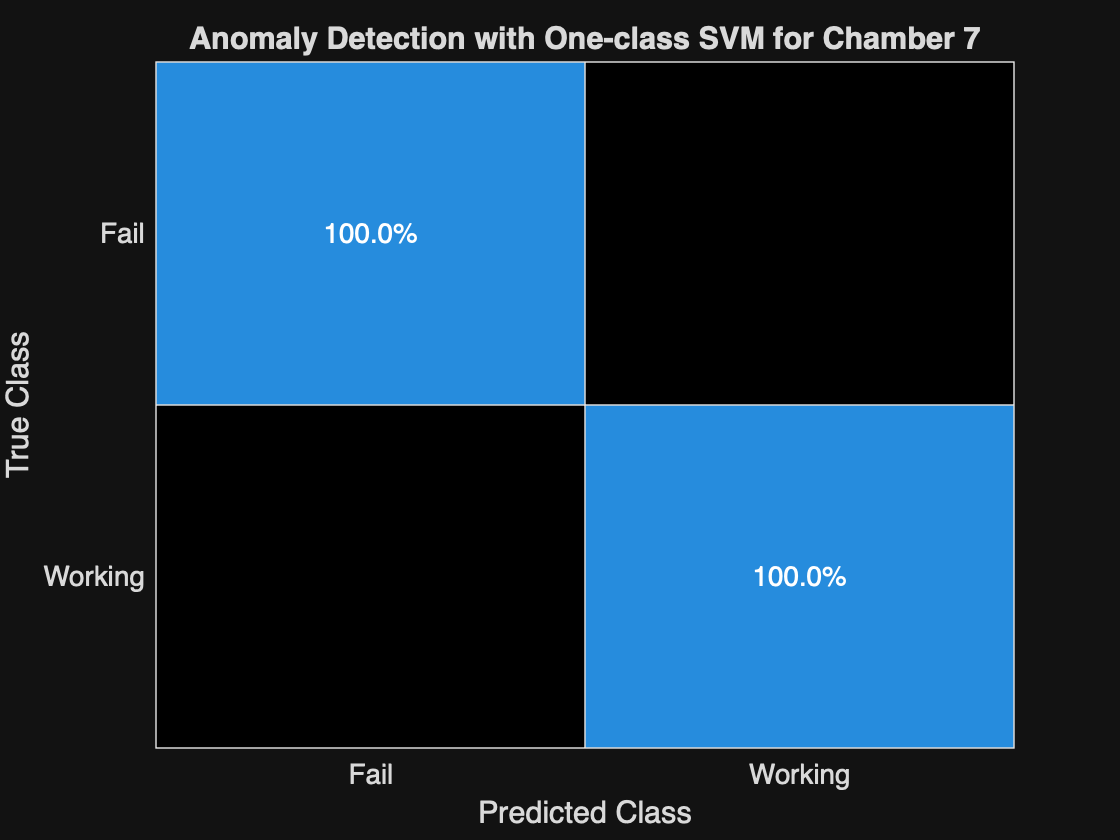

% Validate using the test data
featureTestNoLabels = featureTest(:, 2:end);
isanomalyOCSVM = isanomaly(mdlOCSVM, featureTestNoLabels.Variables, "ScoreThreshold", -0.4);
predOCSVM = categorical(isanomalyOCSVM, [1, 0], ["Fail", "Working"]);

% trueAnomaliesTest = renamecats(trueAnomaliesTest,["Working","Fail"], ["Normal","Fail"]);
figure;
title1= sprintf("Anomaly Detection with One-class SVM for Chamber %d", ii);
confusionchart(trueAnomaliesTest, predOCSVM, Title=title1, Normalization="row-normalized");

%Implement anomaly detection using isolation forest
[mdlIF,~,scoreTrainIF] = iforest(featureNormal{:,2:11},'ContaminationFraction',0, 'NumLearners', 100, "NumObservationsPerLearner", 10);

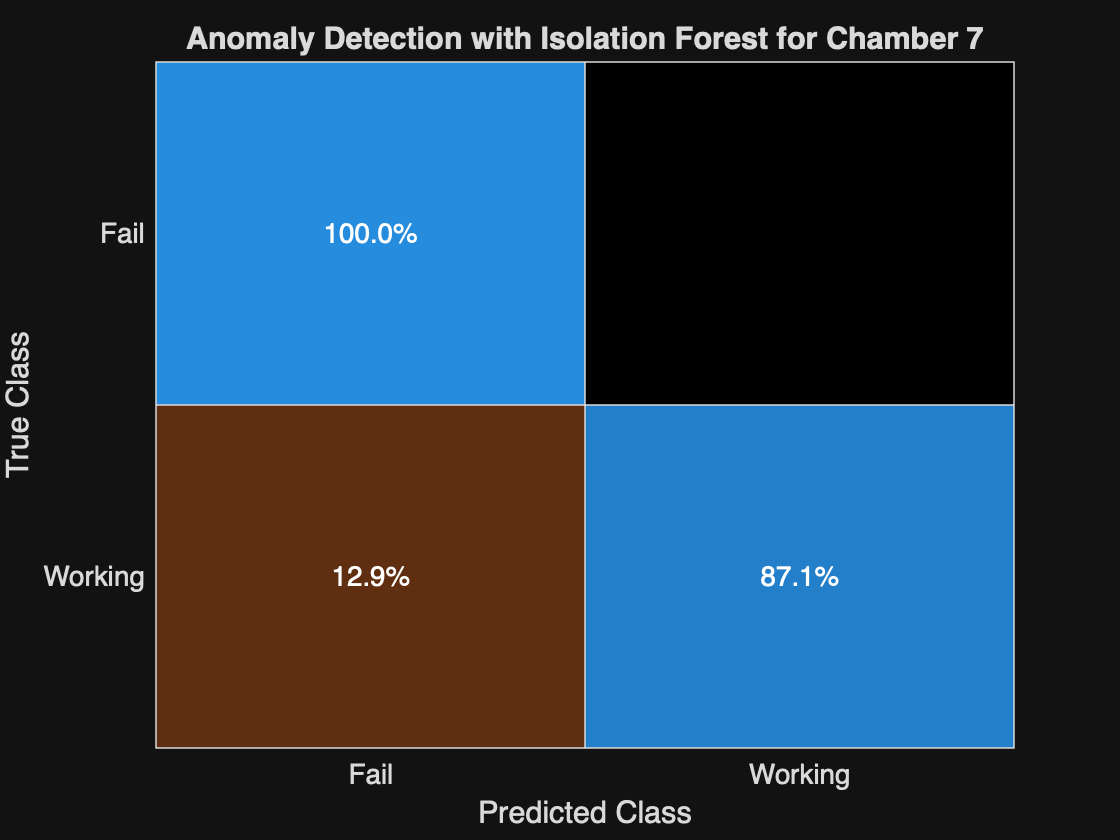

% validate isolation forest model
[isanomalyIF,scoreTestIF] = isanomaly(mdlIF,featureTestNoLabels.Variables, 'ScoreThreshold', 0.535);
predIF = categorical(isanomalyIF, [1, 0], ["Fail", "Working"]);
figure;
title2=sprintf("Anomaly Detection with Isolation Forest for Chamber %d",ii);
confusionchart(trueAnomaliesTest,predIF,Title=title2,Normalization="row-normalized");